# Iterative Integrals

$\frac{dy}{dx} = x^2sin(x)+y
$ on $0 \leq x \leq 1$, $y(0)=0$. 

Initial value problem:


$$\frac{dy}{dx} = f(x,y) =s^2sin(x)+y$$


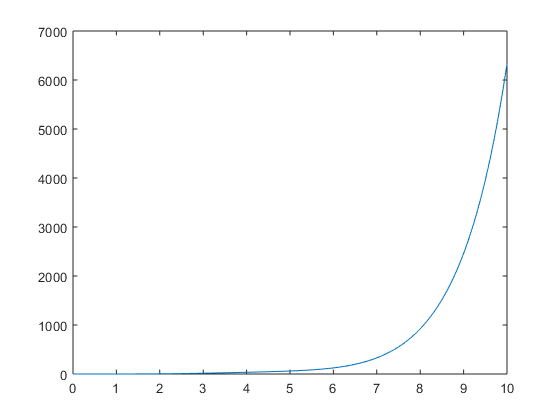

N = 101; a=0; b=10; delX = abs(b-a)/N; %Set interval and delta X
x = linspace(a,b,N);
W = zeros(1,N);                     %Define initial value
f=@(x,y) x^2*sin(x)+y;              %Define equation
for j = 1:N-1
    W(j+1) = W(j) + delX*(f(j*delX,W(j)));  %Calculate values for W
end
plot(x,W)                           %Plot

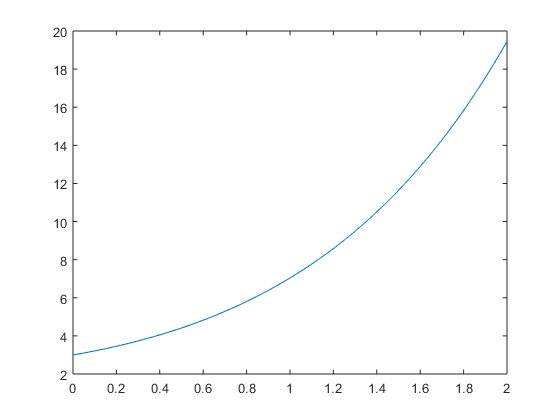

N = 101; a=0; b=2; delX = abs(b-a)/N; %Set interval and delta X
x = linspace(a,b,N);
W = zeros(1,N); W(1)=3;             %Define initial value
f=@(x,y) y+x-1;                     %Define equation
for j = 1:N-1
    W(j+1) = W(j) + delX*(f(j*delX,W(j)));  %Calculate values for W
end
plot(x,W)                           %Plot